# Spatial Temporial Koopman decompsition for crypto valuation prediction

#### Anirudh Bhaskar

#### Anirudh Vadakedathe

#### Rohith Ramakrishnan

## Abstract

A prediction analysis applied on a dynamical system such as crypto currency using the principles of spatio temporial koopman decomposition for a higher dimensions. We go through the basic theory with our data-driven approach using higher order dynamic mode decomposition taking certain dimensions from sentiment analysis from news and tweets generated on the topic "Bitcoin" which is a famous crypto currency in circulation in the economy.

## Introduction

## Singular Value Decomposition

Consider $\vec{x}= \pmatrix{1 \cr 3} $ and $A = \pmatrix{2 & 1 \cr -1 & 1}$, then $\vec{y} = A\bar{x}=\pmatrix{2 & 1 \cr -1 & 1}\pmatrix{1 \cr 3} = \pmatrix{5\cr 2}$. $\overrightarrow{y}$ is basically a rotated and stretched form of $\overrightarrow{x}$. 

Now $\pmatrix{\cos{\theta} & -\sin{\theta} \cr \sin{\theta} & \cos{\theta} }$ is a rotation matrix and $\pmatrix{\alpha & 0 \cr 0 & \alpha}$, where $\alpha$ is a *positive real number*, is a stretching/translational matrix and $A$ is composed of these two.

Now consider a circle in 2-dimensions with its orthogonal direction co-ordinates being $v_1$ and $v_2$.

*(in n-dimensions it would be *$v_1 ,v_2 ,\;\ldotp \ldotp \ldotp \;,v_n$*)*

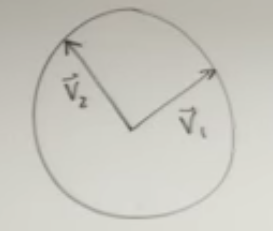

When an $A_{\textrm{mxn}}$, is operated on this circle it becomes an ellipse (*it is rotated and then stretched*):

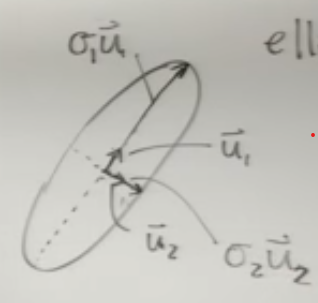

where $u_1$ and $u_2$ are the unit vectors in those directions and $\sigma_1$ and $\sigma_2$ are the distances along the unit vectos.

$\therefore $ $v_1 ,v_2 ,\;\ldotp \ldotp \ldotp \;,v_n$ vector space gets transformed to $u_1 ,u_2 ,\;\ldotp \ldotp \ldotp \;,u_n$ with $\sigma_1 ,\sigma_2 ,\;\ldotp \ldotp \ldotp \;,\sigma_n$ as stretching factors, when multiplied by $A$. The $\sigma_1 ,\sigma_2 ,\;\ldotp \ldotp \ldotp \;,\sigma_n$ are known as the ***singular values***.

Therefore in vector terms: $A\vec{v_j}=\sigma_j \vec{u_j}, \ j=1, 2, ..., n$.


$$\left[ \matrix{\cr A \cr \ } \right]_{mxn}
\left[\matrix{ \vec{v_1} & \vec{v_2} & ... & \vec{v_n} } \right]_{nxn} = 
\left[\matrix{ \vec{u_1} & \vec{u_2} & ... & \vec{u_n} } \right]_{mxn}
\left[\matrix{\sigma_1 &  &  & 0 \cr & \sigma_2 & & \cr  & & \ddots & \cr 0 & & & \sigma_n} \right]_{nxn}$$



$$\therefore
$$

$$\textrm{AV}=\hat{U} \Sigma^ˆ$$


from $V$ and $\hat{U}$ it could be seen that these are unitary transformation matrices and orthogonal too. Thus $V^{-1} =V^*$and ${\hat{U} }^{-1} ={\hat{U} }^*$. On right multiplication with $V^{-1}$ we get

$A=\hat{U} \Sigma^ˆ V^*$ $\longrightarrow$ reduced SVD of A.

Since $\hat{U}$ is of size mxn, m-n extra silent columns can be added to make it mxm and the $\Sigma^ˆ$ can be stretched with m-n rows of 0's to make its size mxn.

$\therefore \  A_{mxn} = U_{mxm}\Sigma_{mxn} V^{*}_{nxn}$ $\longrightarrow$ **Singular Value Decomposition** of $\mathit{\mathbf{A}}$, where 

($\sigma_1 \ge \sigma_2 \ge \;\ldotp \ldotp \ldotp \;\ge \sigma_n \ge 0$).

To get the $U,\Sigma \;\textrm{and}\;V$ matrices we follow these steps:


$$A^T A = (U \Sigma V^*)^T (U \Sigma V^*) \\
A^T A = V \Sigma  U^* U \Sigma V^* \\
A^T A = V \Sigma^2 V^*\\
A^T A V = (V \Sigma^2 V^*)V\\
\therefore A^T A V = \Sigma^2 V$$


This is the same as $\textrm{Av}=\lambda v$, thus by solving this eigen-value problem we would get the $\Sigma^2$ and $V$ values.


$$A A^T = (U \Sigma V^*) (U \Sigma V^*)^T \\
A A^T = U \Sigma V^* V \Sigma U^* \\
A A^T = U \Sigma^2 U^* \\
A A^T U = (U \Sigma^2 U^*)U \\
\therefore A A^T U = \Sigma^2 U$$


clear all;close all;clc;
A = randi(10,3);
[u1, s1, v1] = svd(A);
[v2,ss21] = eig(A'*A);
[u2, ss12] = eig(A*A');
s2 = sqrt(ss12);
u1
u2
disp("*****")
s1
s2
disp("*****")
v1
v2

$A^T A$ $\textrm{and}$ ${\textrm{AA}}^T$ are hermition matrices thus the eigen values are ***always*** *positive, real and distinct*.

## Dynamic Mode Decomposition

A method to reduce the dimensionality of an algorithm. It is seen as an application extracted from the idea of Koopman Spectral analysis.

We consider this method to be more data-driven and on futher explain DMD for higher order dimension non-linear systems. 

Basic idea

Non-linear to best linear approximation,


$$\frac{d\overset{\_}{x} }{\textrm{dt}}=f\left(\overset{\_}{x} ,t,\mu \right)\to \frac{d\overset{\_}{x} }{\textrm{dt}}=A\overset{\_}{x}$$


We measure $x$ for any time-point,


$$x_j =\overset{\_}{x} \left(t_j \right)$$


So,


$$\begin{array}{l}
X=\left\lbrack x_1 \;\;\;x_2 \;\;\;\;x_3 \;\;\cdots \cdots \;\;x_{m-1} \;\right\rbrack \\
X\;\prime =\left\lbrack x_2 \;\;\;x_3 \;\;\;\;x_4 \;\;\cdots \cdots \;\;x_m \;\right\rbrack 
\end{array}$$


Our objective is to find the best matrix that takes $X$ to $X\;\prime \;\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \;X\;\prime =\textrm{AX}$

Here matrix** A** is seen as an operator that takes us $\Delta t$ times into the future from $X\;\textrm{to}\;X\;\prime$

Now from the equation we can calculate $X$ by multiplying its respective pseudo inverse on both sides,

Final equation $\longrightarrow \;A=X\;\prime X^+$ 

This equation is the exact depiction of working of DMD but cannot be practically implemented in data-driven cases. Given our $X$ is has N columns multiplied by N rows of its pseudo inverse we get NxN matrix **A** which is computationally not feasible. So we can define it as an algorithm.

**Step 1:** Decompose $X$ using SVD 

                    
$$X=U\Sigma V^*$$


       We reduce the rank using rank truncation and use that as the subspace for building the model

                    
$$X=U_r \Sigma_r {V^* }_r$$
 

**Step 2:**   

                  
$$\begin{array}{l}
A=X\;\prime X^+ \\
\;\;\;\;=X\;\prime \;V\;\Sigma^{-1} {\;U}^* 
\end{array}$$
 

        We will be working with a similarity transform of A dentoted as $\overset{~}{A}$

                   
$$\begin{array}{l}
\overset{~}{A} =U^* A\;U\\
{\overset{~}{A} }_{\;\textrm{rxr}} ={\;U}^* X\;\prime \;V\;\Sigma^{-1} 
\end{array}$$


**Step 3:**

        we do an eigenvalue decomposition

                    
$$\hat{\;A} W=W\Lambda$$


       where $W\;\textrm{is}\;\left\lbrack \begin{array}{c}
\textrm{eigenvectors}
\end{array}\right\rbrack \;\textrm{and}\;\Lambda \;\textrm{is}\;\left\lbrack \begin{array}{ccc}
\lambda_1  & \cdots  & 0\\
\vdots  & \ddots  & \vdots \\
0 & \cdots  & \lambda_r 
\end{array}\right\rbrack \;$

**Step 4:**

       Bring it back to the original higher rank

                    
$$\phi =X\;\prime \;V\;\Sigma^{-1} \;W\;\;\longrightarrow \;\;\textrm{DMD}\;\textrm{modes}$$



$$X\left(t\right)=\phi {\;e}^{\Omega t} \;b\;\;=\;\sum_{k=1}^r \phi_k \;e^{w_k \;t} \;b_k \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{where}\;\;\;\;\;b=\frac{\phi }{x\left(0\right)}\;$$


x=linspace(-10,10,100); 
t=linspace(0,4*pi,80); dt=t(2)-t(1);
[X,T]=meshgrid(x,t); 

f1=sech(X+3).*(1*exp(i*2.3*T));
f2=(sech(X).*tanh(X)).*(2*exp(i*2.8*T));
f=f1+f2;
 
subplot(2,2,1), surfl(real(f1)), shading interp, colormap(gray), view(-20,60)
subplot(2,2,2), surfl(real(f2)), shading interp,colormap(gray), view(-20,60)
subplot(2,2,3), surfl(real(f)), shading interp,colormap(gray), view(-20,60) 

[u,s,v]=svd(f');
 
figure(2)
subplot(4,3,1), plot(diag(s)/sum(diag(s)),'ko','Linewidth',[2])
subplot(4,1,2), plot(t,v(:,1)/max(v(:,1)),t,v(:,2)/max(v(:,2)),'Linewidth',[2])
subplot(4,1,3), plot(x,u(:,1)/max(u(:,1)),'Linewidth',[2])
subplot(4,1,4), plot(x,u(:,2)/max(u(:,2)),'Linewidth',[2])
X = f.'; X1 = X(:,1:end-1); X2 = X(:,2:end);
r=2;

[U2,Sigma2,V2] = svd(X1,'econ'); U=U2(:,1:r); Sigma=Sigma2(1:r,1:r); V=V2(:,1:r);
Atilde = U'*X2*V/Sigma;    
[W,D] = eig(Atilde);    
Phi = X2*V/Sigma*W;
    
mu = diag(D);
omega = log(mu)/dt;

u0=f(1,:).';
y0 = Phi\u0;  % pseudo-inverse initial conditions
u_modes = zeros(r,length(t));
for iter = 1:length(t)
     u_modes(:,iter) =(y0.*exp(omega*t(iter)));
end
u_dmd = Phi*u_modes;

figure(1)
subplot(2,2,4)
surfl(real(u_dmd.')), shading interp,colormap(gray), view(-20,60)

figure(2), 
subplot(4,3,2), plot(diag(Sigma2)/sum(diag(Sigma2)),'ko','Linewidth',[2])
subplot(4,1,3), hold on, plot(x,-Phi(:,1)/max(Phi(:,1)),'Linewidth',[2])
subplot(4,1,4), hold on, plot(x,Phi(:,2)/max(Phi(:,2)),'Linewidth',[2])

subplot(4,1,3), plot(x,-sech(x).*tanh(x)/max(sech(x).*tanh(x)),':','Linewidth',[2])
subplot(4,1,4), plot(x,sech(x+3)/max(sech(x+3)),':','Linewidth',[2])

##  Higher Order Dynamic Mode Decomposition

Lets assume a dynammic system given by the vector state variable **𝑣**(𝑡), of size 𝐽, we consider a set of 𝐾 snapshots at equispaced values of *t*

				
$$v_k \equiv v\left(t_k \right)\;$$


where $t_k =t_1 +\left(k-1\right)\ldotp \Delta t\;,\textrm{for}\;\textrm{𝑘}=1,\ldotp \ldotp \ldotp ,\textrm{𝐾}$

Assuming the dynamical system is infinite-dimensional, the finite- dimensional state vector V generally results from spatial discretization. The snapshots

are organized in a snapshot matrix (whose columns are the snapshots), as 

                            
$$V_1^k =\left\lbrack \upsilon_1 \;\;\;\;\upsilon_2 \;\;\;\ldotp \ldotp \ldotp \;\;\;\upsilon_k \right\rbrack$$


**Metrics: ** *relative root mean square *(RMS) error, defined as 

            
$$\textrm{error}=\sqrt{\frac{\sum_{k=1}^K {\left\|\;v_k^{\textrm{approx}} \;-v_k \right\|}_2^2 }{\sum_{k=1}^K {\left\|\;v_k \right\|}_2^2 }}$$


### Algorithm:

**SVD** : 

For dimensionality reduction, truncated SVD is applied to $V_1^k$, which yields,

                $V_1^k \approx P\Sigma Q^T$ $\equiv P\hat{{{\mathrm{T}}_1 }^K }$    (or $\upsilon_k$ $\equiv P\hat{t_k }$)

                            where $\hat{{\mathrm{T}}_1 }$ = $\Sigma Q^T$ 

where the matrix $\hat{{{\mathrm{T}}_1 }^K }$ is known as the dimension-reduced snapshot matrix and their columns, the *dimension-reduced snapshots*,$\hat{{\;t}_k }$.

**DMDd**: 	

For ordinary DMD, we consider the Koopman Assumption which can be formulated as,

                    
$${\hat{t} }_{k+1} ={\hat{R} }^{t\;} \ldotp {\hat{t} }_k$$


Where the M x M matrix ${\hat{R} }^{t\;}$is computed from dimension-reduced snapshots via pseudoinverse.

Reduced Snapshots can be represented by,

               
$$\hat{t_{k+d} } \approx \hat{R_1 } \hat{t_{k+d-1} } +\hat{R_2 } \hat{t_{k+d-2} \;} +\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp +\hat{R_k } \hat{t_k \;} \;$$


The enlarged snapshots can be represented by,

                        
$$\tilde{t_k } \equiv \left\lbrack \begin{array}{c}
\hat{t_k } \\
\hat{t_{k+1} } \\
\ldotp \ldotp \ldotp \\
\hat{t_{k+d-2} } \\
\hat{t_{k+d-1} } 
\end{array}\right\rbrack$$


SVD is applied to $\tilde{t_k }$ , a second dimension reduction that gives a new set of enlarges dimension-reduced snapshots, $\hat{\tilde{t_k } }$ 

which will satisfy -  $\hat{\tilde{t_{k+1} } } =\tilde{R^t } \ldotp \hat{\tilde{t_k } }$ , where $\tilde{R^t }$ is computed via the pseudo-inverse as defined above.

t = linspace(0,30,1000);
V = sqrt(1 + (1/2).*sin(t).*sin(sqrt(3)*t));
d = 800;
varepsilon1 = 10^-10;
varepsilon = 10^-4;
[Vreconst,~] =DMDd_SIADS(d,V,t,varepsilon1,varepsilon)
plot(t,V)
hold on
plot(t,real(Vreconst),'.')
legend("Original Data","Reconstruction")
t = linspace(0,100,length(Close));
d = 46;
varepsilon1 = 10^-10;
varepsilon = 10^-4;
[Vreconst,~] =DMDd_SIADS(d,Close',t,varepsilon1,varepsilon)
figure
plot(t,Close)
hold on
plot(t,real(Vreconst))
legend("Original Data","Reconstruction")

## Spatio Temporal Koopman Decomposition

For simplicity pupose we will consider one spatio-variable X and a temporal-variable T for and snapshot $V_1^k$ of dimension J x K.

Lets consider a toy model with discritised values $x_j$ = $x_1 +j\Delta x$  and $t_j$ = $t_1 +k\Delta t$, for j = 1,...,J and k = 1,....,K

STKD can be represented by 


$$\upsilon \left(x_j \;,t_k \right)\;=\sum_{m,n} a_{\textrm{mn}} \;u_{\textrm{mn}} \;e^{\left(v_m +ik_m \right)x_j +\left(\delta_n +i\omega_m \right)t_k }$$


$u_n$ are conveniently normalized spatial modes, $a_n$ > 0 are the mode amplitudes, and 𝛿𝑛 and 𝜔𝑛 ; $v_m \;\textrm{and}\;ik_m$ are the associated 

growth rates and frequencies, respectively. 

#### STEP : 1 -

As in HODMD, SVD is performed on the Snapshot $V_1^k$ with a tunable value $\epsilon_1$which determines the number of SVD modes M. 

$V_1^k$ = $P\sum Q^T$ $\equiv {\left(\hat{X_1^J } \right)}^T$$\hat{T_1^K }$,

$\hat{X_1^J }$ = $\sqrt{\sum }P^T$

$\hat{T_1^J }$ = $\sqrt{\sum }Q^T$

These matrices are the reduced spatial and temporal snapshots and their columns are $\hat{x_j }$and $\hat{t_k }$ are the reduced spatial and temporal snapshots.

#### STEP : 2 -

The HODMD algorithm is applied to thr spatial and temporal components

$\hat{x_j } \approx \sum_{m=1}^M {\hat{a_m } }^x \ldotp {\hat{q_m } }^x e^{\left(v_m +ik_m \right)x_j }$ , for j=1,...,J

$\hat{t_k } \approx \sum_{n=1}^N {\hat{a_n } }^t \ldotp {\hat{q_n } }^{t\;} e^{\left(\delta_n +i\omega_n \right)t_k }$ , for k=1,...,K

The numbers of retained modes, M and N, are the *spec- tral spatial and temporal complexities*, respectively, and are selected in terms of the spatial 

and temporal amplitudes, ${\hat{a_m } }^x$ and ${\hat{a_n } }^t$. M and N are the smallest values of the indexes 𝑚 and 𝑛 such that 


$$\frac{{\hat{a_{M+1} } }^x \;}{{\hat{a_1 } }^x }<\varepsilon_2$$



$$\frac{{\hat{a_{N+1} } }^x \;}{{\hat{a_1 } }^x }<\varepsilon_2$$


Illustration of the STKD in a toy model,

u (𝑥, 𝑡) = (0.5 + sin 𝑥).[2.cos($k_1 \ldotp x-w_1 \ldotp t$) + (0.5).cos($k_2 \ldotp x-w_2 \ldotp t$)]

x = linspace(0,10,100);
t = linspace(0,100,100);
U = zeros(length(x));

varepsilon1 = 10^-8;
varepsilon2 = 10^-7;

for i=1:length(x)
    for j=1:length(t)
        X = x(i); T = t(j);
        U(i,j) = (0.5 + sin(X)) * (2*cos(2*X - (2*pi/45)*T) + 0.5*cos(10*X - sqrt(10)*T));
    end
end
figure



[Vreconst,Modes,Amplitudes,Amplitudesx,GrowthRatex,Frequencyx,Amplitudest,GrowthRatet,Frequencyt]=...
CalculateDMDdSdT(10,1,x,t,U,varepsilon1,varepsilon2);
contourf(U)
figure
contourf(abs(Vreconst))
shading('interp')
colormap(jet)

function  [Vreconst,deltas,omegas,amplitude,modes] =DMDd_SIADS(d,V,Time,varepsilon1,varepsilon)


%%%%%%%%%%%%%%%%%%%%%%%%%  DMD-d %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% This function solves the HODMD algorithm presented in               %%%
%%% Le Clainche & Vega, SIAM J. on Appl. Dyn. Sys. 16(2):882-925, 2017  %%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% %% INPUT: %%
%%% d: parameter of DMD-d (higher order Koopman assumption)
%%% V: snapshot matrix
%%% Time: vector time
%%% varepsilon1: first tolerance (SVD)
%%% varepsilon: second tolerance (DMD-d modes)
%%% %% OUTPUT: %%
%%% Vreconst: reconstruction of the snapshot matrix V
%%% deltas: growht rate of DMD modes
%%% omegas: frequency of DMD modes(angular frequency)
%%% amplitude: amplitude of DMD modes
%%% modes: DMD modes
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


[J,K]=size(V);

% STEP 1: SVD of the original data

[U,Sigma,T]=svd(V,'econ');
sigmas=diag(Sigma);
n=length(sigmas);

NormS=norm(sigmas,2);
kk=0;
for k=1:n
    if norm(sigmas(k:n),2)/NormS>varepsilon1
        kk=kk+1;
    end
end

U=U(:,1:kk);

% Create reduced snapshots matrix
hatT=Sigma(1:kk,1:kk)*T(:,1:kk)';
[N,~]=size(hatT);

% Create the modified snapshot matrix
tildeT=zeros(d*N,K-d+1);
for ppp=1:d
    tildeT((ppp-1)*N+1:ppp*N,:)=hatT(:,ppp:ppp+K-d);
end

% Dimension reduction
[U1,Sigma1,T1]=svd(tildeT,'econ');
sigmas1=diag(Sigma1);

Deltat=Time(2)-Time(1);
n=length(sigmas1);

NormS=norm(sigmas1,2);
kk1=0;
for k=1:n
    RRMSEE(k)=norm(sigmas1(k:n),2)/NormS;
    if RRMSEE(k)>varepsilon1
        kk1=kk1+1;
    end
end


U1=U1(:,1:kk1);
hatT1=Sigma1(1:kk1,1:kk1)*T1(:,1:kk1)';

% Reduced modified snapshot matrix
[~,K1]=size(hatT1);
[tildeU1,tildeSigma,tildeU2]=svd(hatT1(:,1:K1-1),'econ');

% Reduced modified Koopman matrix
tildeR=hatT1(:,2:K1)*tildeU2*inv(tildeSigma)*tildeU1';
[tildeQ,tildeMM]=eig(tildeR);
eigenvalues=diag(tildeMM);

M=length(eigenvalues);
qq=log(eigenvalues);
deltas=real(qq)/Deltat;
omegas=imag(qq)/Deltat;

Q=U1*tildeQ;
Q=Q((d-1)*N+1:d*N,:);
[NN,MMM]=size(Q);

for m=1:MMM
    NormQ=Q(:,m);
    Q(:,m)= Q(:,m)/norm(NormQ(:),2);
end

% Calculate amplitudes
Mm=zeros(NN*K,M);
Bb=zeros(NN*K,1);
aa=eye(MMM);
for k=1:K
    Mm(1+(k-1)*NN:k*NN,:)=Q*aa;
    aa=aa*tildeMM;
    Bb(1+(k-1)*NN:k*NN,1)=hatT(:,k);
end

[Ur,Sigmar,Vr]=svd(Mm,'econ');
a=Vr*(Sigmar\(Ur'*Bb));

u=zeros(NN,M);
for m=1:M
    u(:,m)=a(m)*Q(:,m);
end
amplitude=zeros(M,1);

for m=1:M
    aca=U*u(:,m);
    amplitude(m)=norm(aca(:),2)/sqrt(J);
end

UU=[u;deltas';omegas';amplitude']';
UU1=sortrows(UU,-(NN+3));

UU=UU1';
u=UU(1:NN,:);
deltas=UU(NN+1,:);
omegas=UU(NN+2,:);
amplitude=UU(NN+3,:);
kk3=0;

for m=1:M
    if amplitude(m)/amplitude(1)>varepsilon
        kk3=kk3+1;
    else
    end
end

u=u(:,1:kk3);
deltas=deltas(1:kk3);
omegas=omegas(1:kk3);
amplitude=amplitude(1:kk3);

% Reconstruction of the original snapshot matrix
hatTreconst=zeros(N,K);
for k=1:K
    hatTreconst(:,k)= ContReconst_SIADS(Time(k),Time(1),u,deltas,omegas);
end

Vreconst=U*hatTreconst;

% Calculation of DMD modes
modes=zeros(J,kk3);
amplitude0=zeros(kk3,1);
for m=1:kk3
    NormMode=norm(U*u(:,m),2)/sqrt(J);
    amplitude0(m)=NormMode;
    modes(:,m)=U*u(:,m)/NormMode;
end
end